# Experiment 3_1

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

### Part 1: |𝐻(𝑒𝑗𝜔)|^2

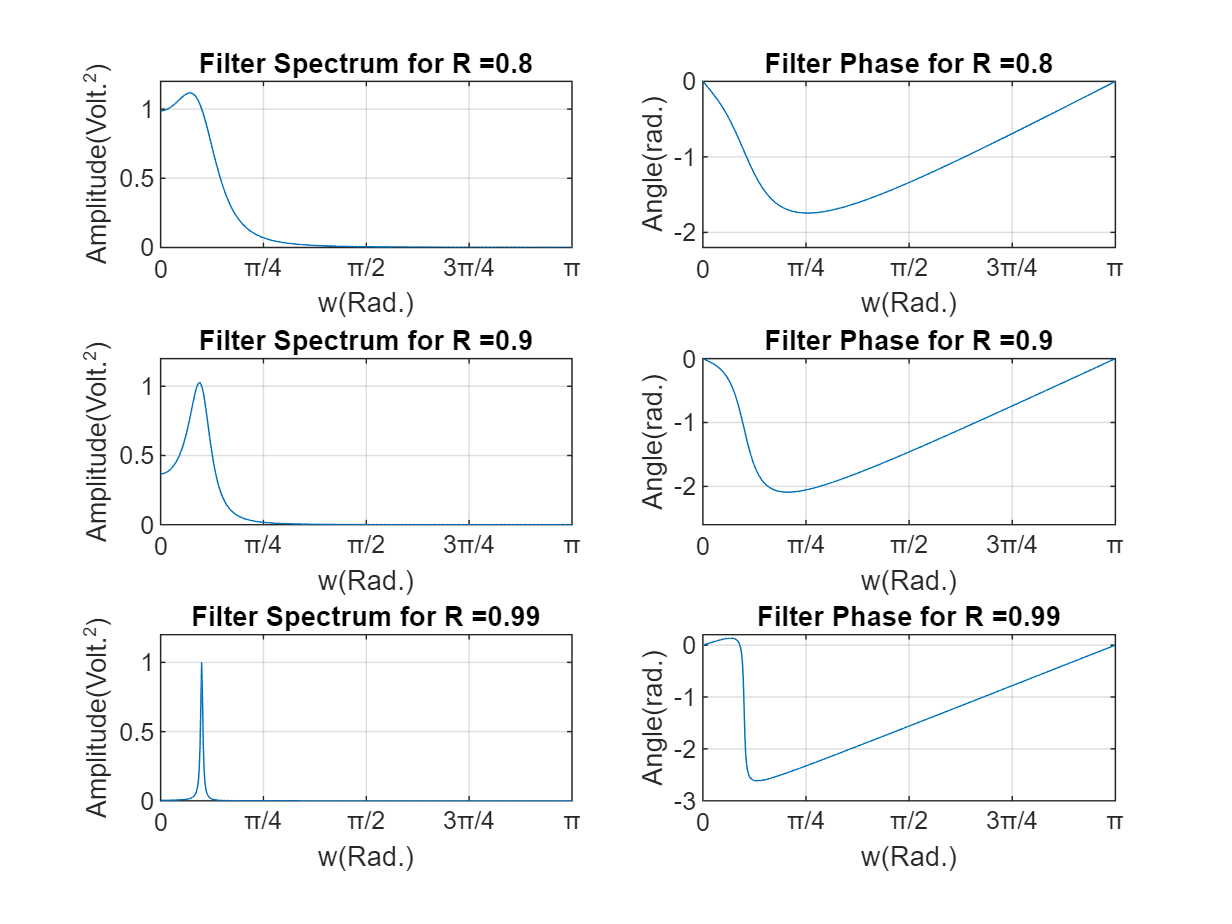

fs = 10000;
f0 = 500;
w0 = 2*pi*f0/fs;

omega = linspace(0, pi, 512);
omega_normalized = omega / pi;

tick_positions = [0, 1/4, 1/2, 3/4, 1];
tick_labels = {'0', '\pi/4', '\pi/2', '3\pi/4', '\pi'};

R_vals = [0.8, 0.9, 0.99];
ylim_phase_list = [-2.2, 0; -2.6, 0; -3, 0.2]; 

figure("Name","Filters spectrum and phase");
for i = 1:length(R_vals)
    R = R_vals(i);
    
    a1 = -2*R*cos(w0);
    a2 = R^2;
    G = (1 - R) * sqrt(1 - 2*R*cos(2*w0) + R^2);
    
    z = exp(1j * omega); 
    Hz = G ./ (1 + a1 ./ z + a2 ./ z.^2);
    
    H_squared = abs(Hz).^2;
    H_phase = angle(Hz);
    
    % Magnitude plot
    subplot(3,2,2*i-1);
    plot(omega_normalized, H_squared);
    title(['Filter Spectrum for R =' num2str(R)]);
    xlabel('w(Rad.)');
    ylabel('Amplitude(Volt.^2)');
    xticks(tick_positions);
    xticklabels(tick_labels);
    ylim([0 1.2]);
    grid on;

    % Phase plot
    subplot(3,2,2*i);
    plot(omega_normalized, H_phase);
    title(['Filter Phase for R =' num2str(R)]);
    xlabel('w(Rad.)');
    ylabel('Angle(rad.)');
    xticks(tick_positions);
    xticklabels(tick_labels);
    ylim(ylim_phase_list(i, :));  
    grid on;
end

### Part 2: h[n]

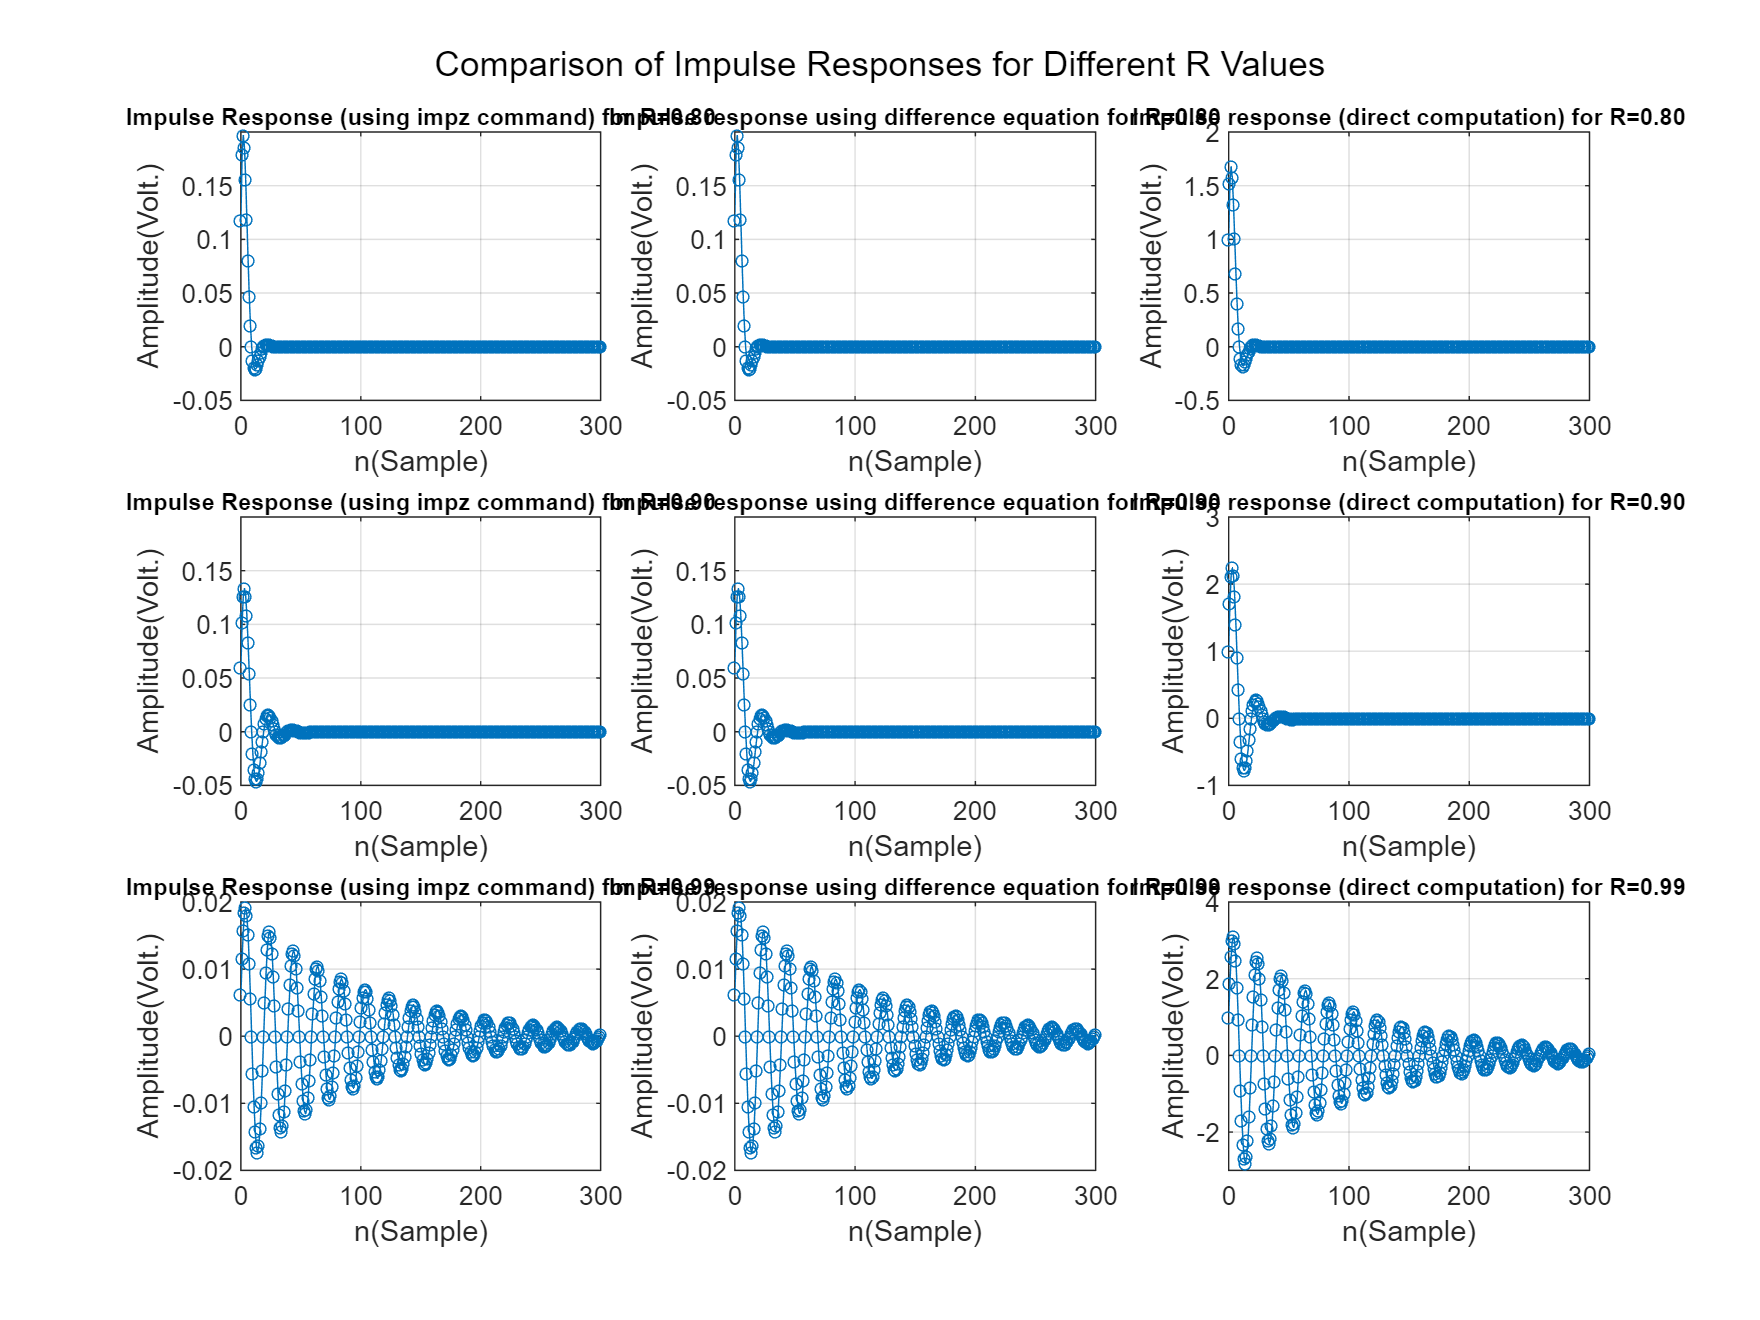

f0 = 500;            
fs = 10e3;           
omega0 = 2 * pi * f0 / fs; 

R_values = [0.8, 0.9, 0.99];
N = 301;             
n = 0:N-1;          

figure("Name","impulse responses");
set(gcf, 'Position', [100, 100, 2400, 1800]); 

for i = 1:length(R_values)
    R = R_values(i);
    a1 = -2 * R * cos(omega0);
    a2 = R^2;
    G = (1 - R) * sqrt(1 - 2 * R * cos(2 * omega0) + R^2); %

    % Method 1: Using impz command
    b_impz = G;
    a_impz = [1, a1, a2];
    h_impz = impz(b_impz, a_impz, N);

    % Method 2: Using difference equation
    h_diff = zeros(1, N);
    x = zeros(1, N);
    x(1) = 1;

    w1 = 0; % y[n-1] equivalent
    w2 = 0; % y[n-2] equivalent

    for k = 1:N
        % y[n] = -a1*y[n-1] - a2*y[n-2] + G*x[n]
        h_diff(k) = -a1 * w1 - a2 * w2 + G * x(k);
        w2 = w1; 
        w1 = h_diff(k); 
    end

    % Method 3: Direct computation using formula
    h_direct = (G / sin(omega0)) * (R.^n) .* sin(omega0 * n + omega0);

    % Subplot 1 : impz command
    subplot(3, 3, (i-1)*3 + 1);
    plot(n, h_impz, 'o-', 'MarkerSize', 4, 'MarkerFaceColor', 'none', 'Color', [0 0.4470 0.7410]); % Hollow circles, connected by lines
    title(sprintf('Impulse Response (using impz command) for R=%.2f', R), 'FontSize', 8); % Reduced font size for title
    xlabel('n(Sample)');
    ylabel('Amplitude(Volt.)');
    grid on;
    xlim([0 300]);
    if R == 0.8 || R == 0.9
        ylim([-0.05 0.2]);
    else 
        ylim([-0.02 0.02]);
    end

    % Subplot 2: Difference equation
    subplot(3, 3, (i-1)*3 + 2);
    plot(n, h_diff, 'o-', 'MarkerSize', 4, 'MarkerFaceColor', 'none', 'Color', [0 0.4470 0.7410]); % Hollow circles, connected by lines
    title(sprintf('Impulse response using difference equation for R=%.2f', R), 'FontSize', 8); % Reduced font size for title
    xlabel('n(Sample)');
    ylabel('Amplitude(Volt.)');
    grid on;
    xlim([0 300]);
    if R == 0.8 || R == 0.9
        ylim([-0.05 0.2]);
    else 
        ylim([-0.02 0.02]);
    end
    
    % Subplot 3 : Direct computation
    subplot(3, 3, (i-1)*3 + 3);
    plot(n, h_direct ./ G, 'o-', 'MarkerSize', 4, 'MarkerFaceColor', 'none', 'Color', [0 0.4470 0.7410]); % Hollow circles, connected by lines
    title(sprintf('Impulse response (direct computation) for R=%.2f', R), 'FontSize', 8); % Reduced font size for title
    xlabel('n(Sample)');
    ylabel('Amplitude(Volt.)');
    grid on;
    xlim([0 300]);
    if R == 0.8
        ylim([-0.5 2]);
    elseif R == 0.9
        ylim([-1 3]); 
    else 
        ylim([-3 4]); 
    end
end

sgtitle('Comparison of Impulse Responses for Different R Values', 'FontSize', 12); 

### Part 3: Denoising with H(z)

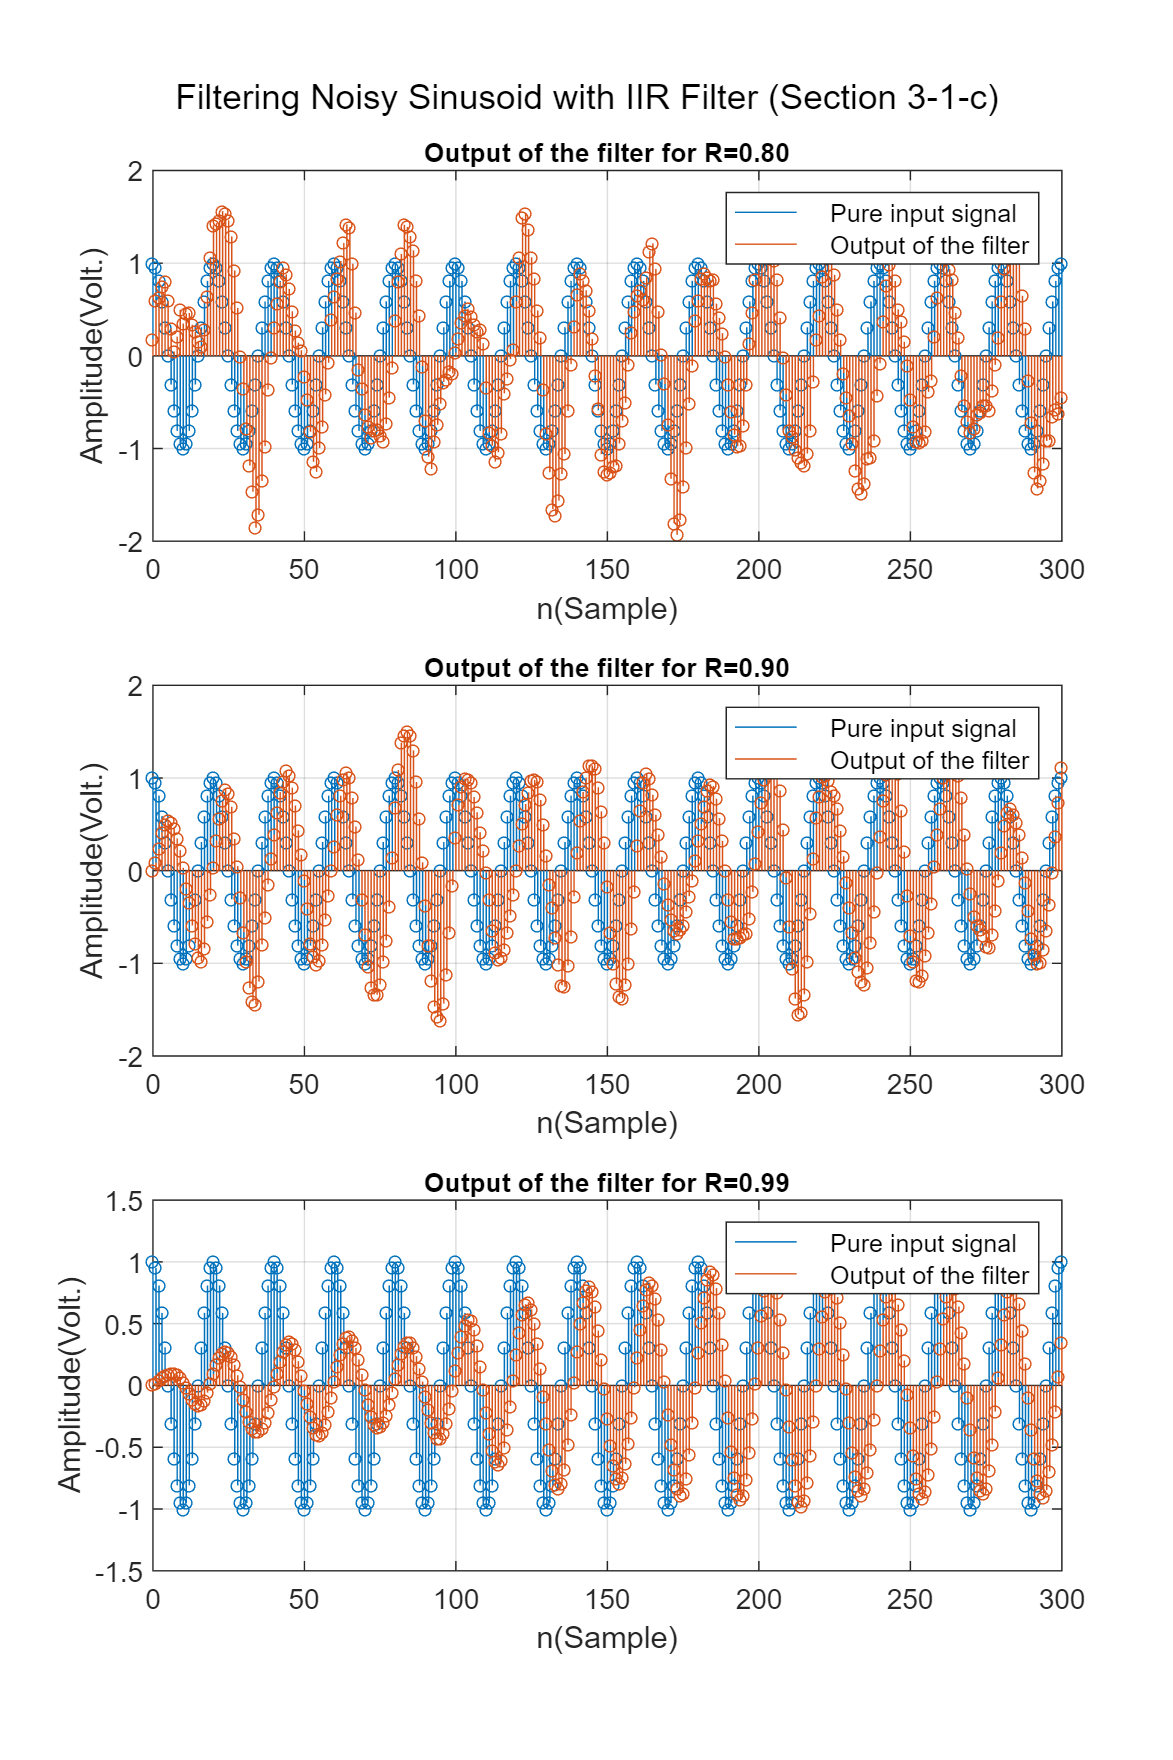

f0 = 500;          
fs = 10e3;         
omega0 = 2 * pi * f0 / fs; 

R_values = [0.8, 0.9, 0.99]; 
N_samples = 301;            
n = 0:N_samples-1;          


figure("Name","Filtering of the noisy signal");
set(gcf, 'Position', [100, 100, 1000, 1500]); 


s_n = cos(omega0 * n); 

for i = 1:length(R_values)
    R = R_values(i);

    % Coefficients (a1, a2,G) calculation
    a1 = -2 * R * cos(omega0);
    a2 = R^2;
    G = (1 - R) * sqrt(1 - 2 * R * cos(2 * omega0) + R^2);

   
    v_n = randn(1, N_samples);
    x_n = s_n + v_n;

    % Method: Filter x[n] using the sample-by-sample processing algorithm (difference equation)
    y_n = zeros(1, N_samples); 
    w1 = 0; 
    w2 = 0; 

    for k = 1:N_samples
        % y[n] = -a1*w1 - a2*w2 + G*x[n]
        current_x = x_n(k);
        y_n(k) = -a1 * w1 - a2 * w2 + G * current_x;
        w2 = w1; 
        w1 = y_n(k); 
    end


    subplot(3, 1, i); 

    stem(n, s_n, 'Color', [0 0.4470 0.7410], 'Marker', 'none'); 
    hold on;
    plot(n, s_n, 'o', 'MarkerSize', 4, 'MarkerFaceColor', 'none', 'Color', [0 0.4470 0.7410]);

    stem(n, y_n, 'Color', [0.8500 0.3250 0.0980], 'Marker', 'none'); 
    plot(n, y_n, 'o', 'MarkerSize', 4, 'MarkerFaceColor', 'none', 'Color', [0.8500 0.3250 0.0980]); % Hollow circles

    hold off; 

    title(sprintf('Output of the filter for R=%.2f', R), 'FontSize', 9); % Title for the subplot, smaller font
    xlabel('n(Sample)');
    ylabel('Amplitude(Volt.)');
    grid on;
    xlim([0 300]); 

    if R == 0.8 || R == 0.9
        ylim([-2 2]);
    else 
        ylim([-1.5 1.5]);
    end

    legend('Pure input signal', '', 'Output of the filter', '', 'Location', 'northeast'); 
    
end

sgtitle('Filtering Noisy Sinusoid with IIR Filter (Section 3-1-c)', 'FontSize', 12);

### Part 4: Filter v[n] seperately

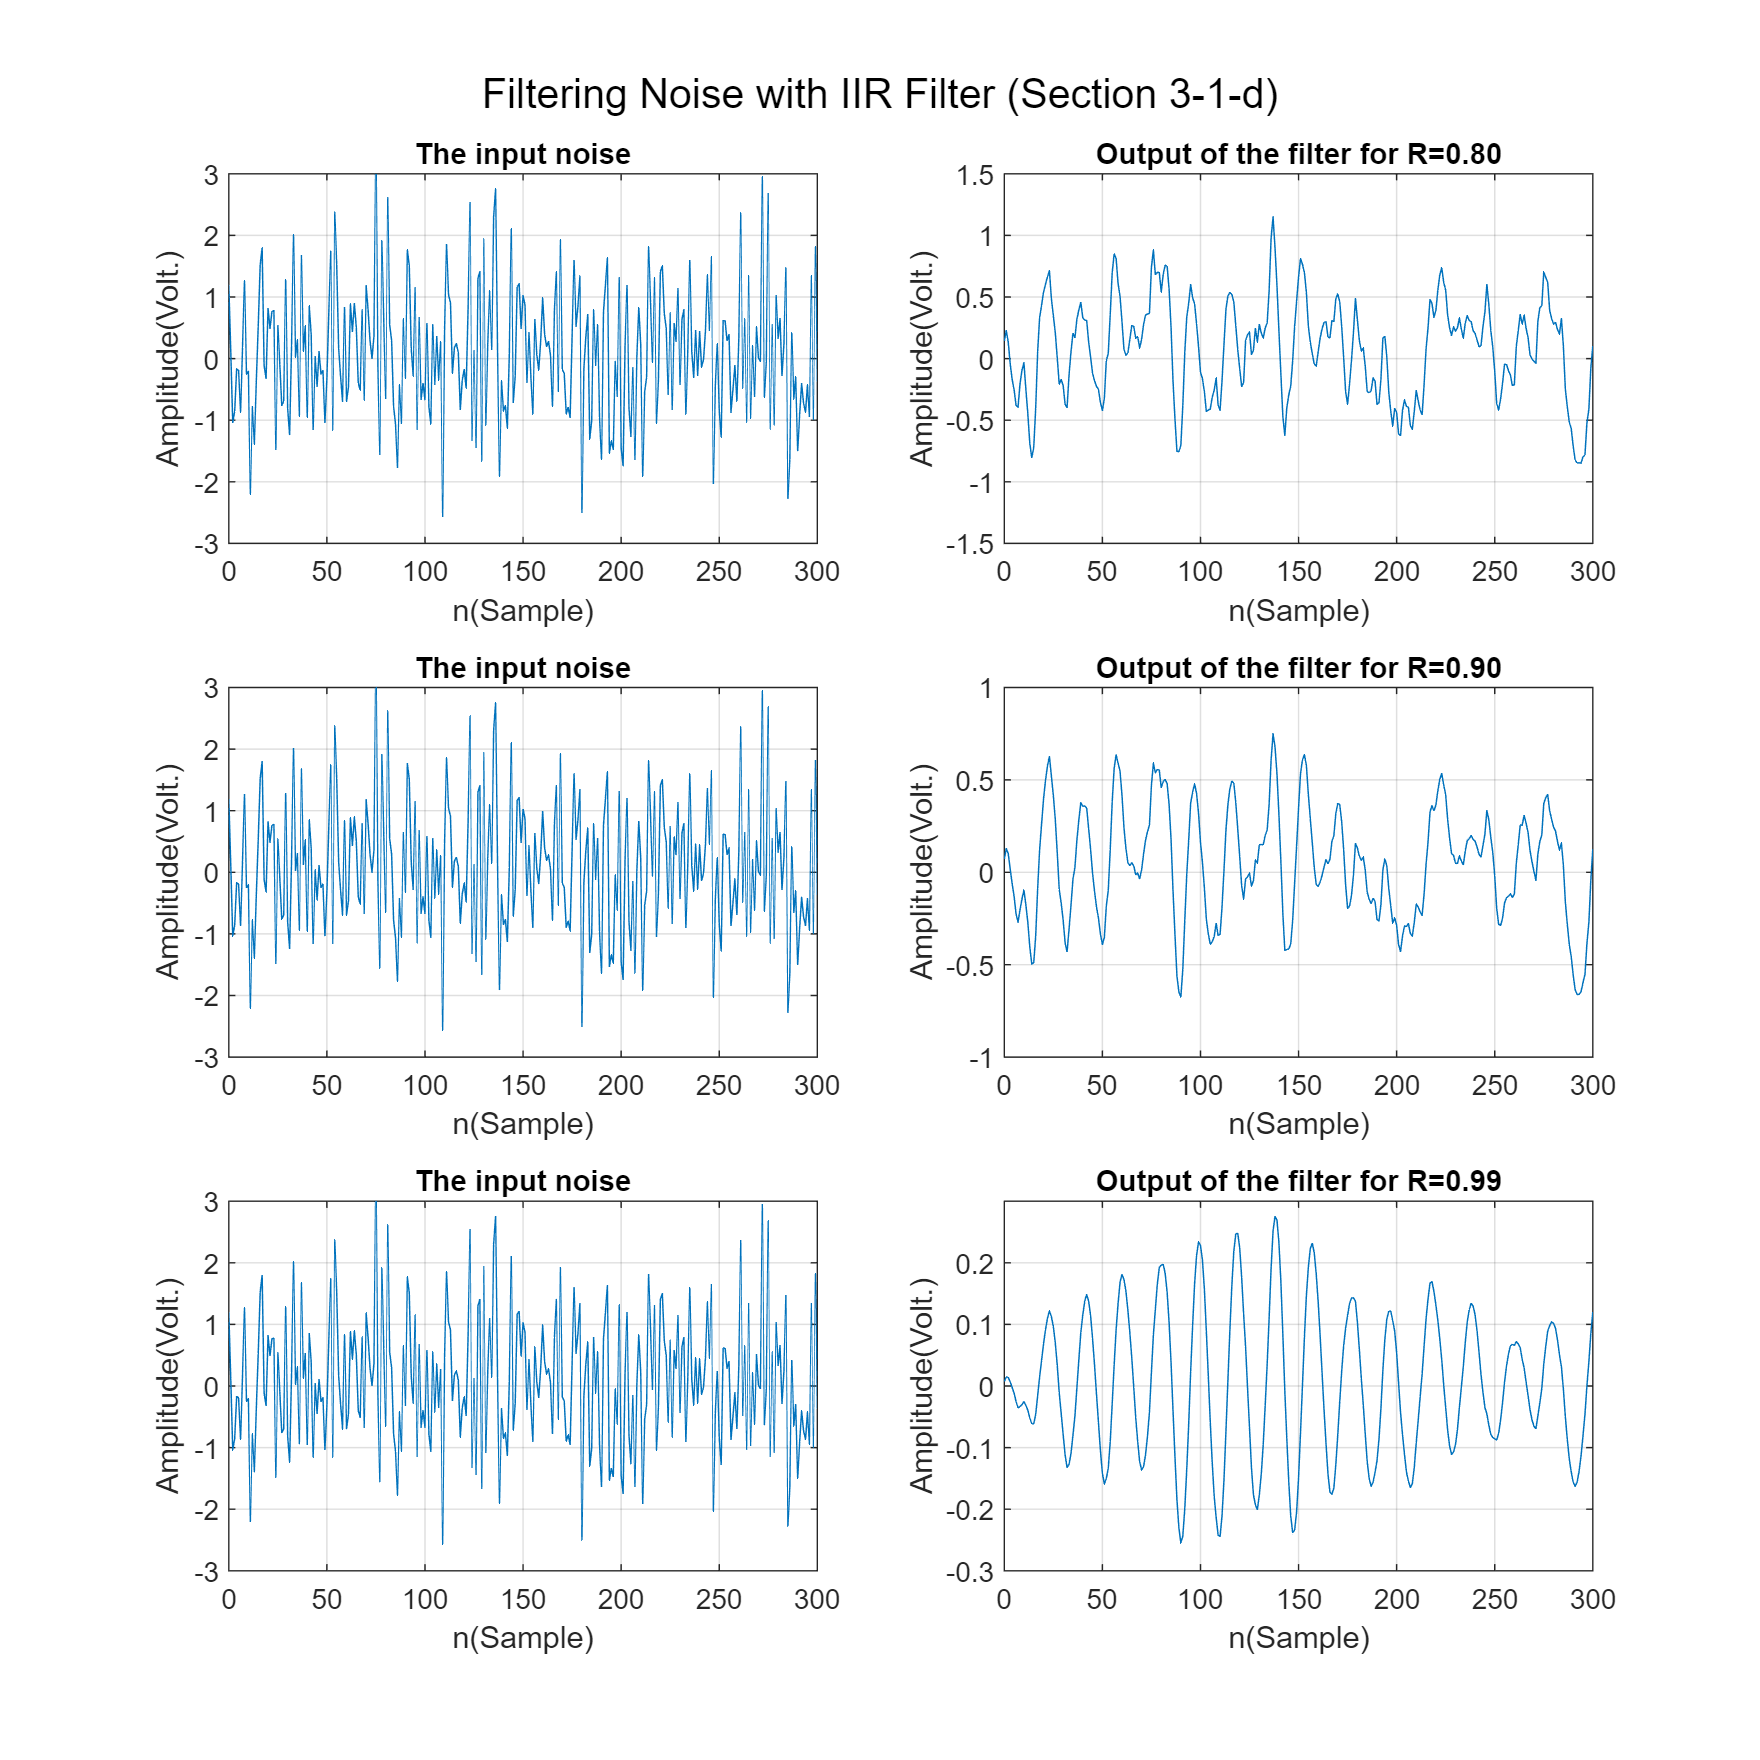

f0 = 500;           
fs = 10e3;         
omega0 = 2 * pi * f0 / fs; 

R_values = [0.8, 0.9, 0.99]; 
N_samples = 301;            
n = 0:N_samples-1;           


figure("Name","Filtering noise with IIR filter");
set(gcf, 'Position', [100, 100, 1200, 1200]); 

v_n = randn(1, N_samples); % Random noise (Gaussian, mean 0, variance 1)

for i = 1:length(R_values)
    R = R_values(i);

    % Coefficients (a1, a2,G) calculation
    a1 = -2 * R * cos(omega0);
    a2 = R^2;
    G = (1 - R) * sqrt(1 - 2 * R * cos(2 * omega0) + R^2);

    % Method: Filter v[n] using the sample-by-sample processing algorithm (difference equation)
    yv_n = zeros(1, N_samples); 
    w1 = 0; 
    w2 = 0; 

    for k = 1:N_samples
        % y[n] = -a1*y[n-1] - a2*y[n-2] + G*x[n]
        current_v = v_n(k);
        yv_n(k) = -a1 * w1 - a2 * w2 + G * current_v;
        w2 = w1; 
        w1 = yv_n(k);
    end


    subplot(3, 2, (i-1)*2 + 1); 
    plot(n, v_n, 'Color', [0 0.4470 0.7410]); 
    title('The input noise', 'FontSize', 10);
    xlabel('n(Sample)');
    ylabel('Amplitude(Volt.)');
    grid on;
    xlim([0 300]);
    ylim([-3 3]); 

  
    subplot(3, 2, (i-1)*2 + 2); 
    plot(n, yv_n, 'Color', [0 0.4470 0.7410]); 
    title(sprintf('Output of the filter for R=%.2f', R), 'FontSize', 10);
    xlabel('n(Sample)');
    ylabel('Amplitude(Volt.)');
    grid on;
    xlim([0 300]);

    
    if R == 0.8
        ylim([-1.5 1.5]);
    elseif R == 0.9
        ylim([-1 1]);
    else
        ylim([-0.3 0.3]);
    end
end

sgtitle('Filtering Noise with IIR Filter (Section 3-1-d)', 'FontSize', 14);

Filter only passes $\omega_0$. So, the noise after passing through the filter is not a white noise anymore. It will become a sinusoidal signal with a little oscillation in its amplitude.

### Part 5: Using std to calculate approximation of NRR

f0     = 500;
fs     = 10e3;
omega0 = 2*pi*f0/fs;

R_values    = [0.8, 0.9, 0.99];
N_noise     = 50000;    
N_impulse   = 10000;    
M_trials    = 5;        

for R = R_values
    a1 = -2*R*cos(omega0);
    a2 = R^2;
    G  = (1-R)*sqrt(1 - 2*R*cos(2*omega0) + R^2);

    nrr_emp_runs = zeros(1,M_trials);
    for m = 1:M_trials
        v = randn(1,N_noise);
        y = filter(G, [1 a1 a2], v);
        nrr_emp_runs(m) = var(y)/var(v);
    end
    nrr_emp = mean(nrr_emp_runs);

    nrr_th = (G^2) ...
        / (2 * sin(omega0)^2) ...
        * ( 1/(1 - R^2) ...
        - (cos(2*omega0) - R^2) ...
        / (1 - 2*R^2*cos(2*omega0) + R^4) );

    imp = [1 zeros(1,N_impulse-1)];
    h   = filter(G, [1 a1 a2], imp);
    nrr_imp = sum(h.^2);

    fprintf('\nNRR for R = %.1f\n', R);
    fprintf('Using the variance of signals:       %.4f\n', nrr_emp);
    fprintf('Using the formula (wrong formula):     %.4f\n', nrr_th);
    fprintf('Using the energy of the impulse response: %.4f\n', nrr_imp);

end


NRR for R = 0.8


Using the variance of signals:       0.1694


Using the formula (wrong formula):     0.1683


Using the energy of the impulse response: 0.1683



NRR for R = 0.9


Using the variance of signals:       0.0974


Using the formula (wrong formula):     0.0975


Using the energy of the impulse response: 0.0975



NRR for R = 1.0


Using the variance of signals:       0.0098


Using the formula (wrong formula):     0.0100


Using the energy of the impulse response: 0.0100
